# Train Sensor Fusion Network

Live script used to train sensor fusion network

load("SFnet.mat","Y_Train","X_Test");    

## Visualize Sensor Fusion Double Banana layers

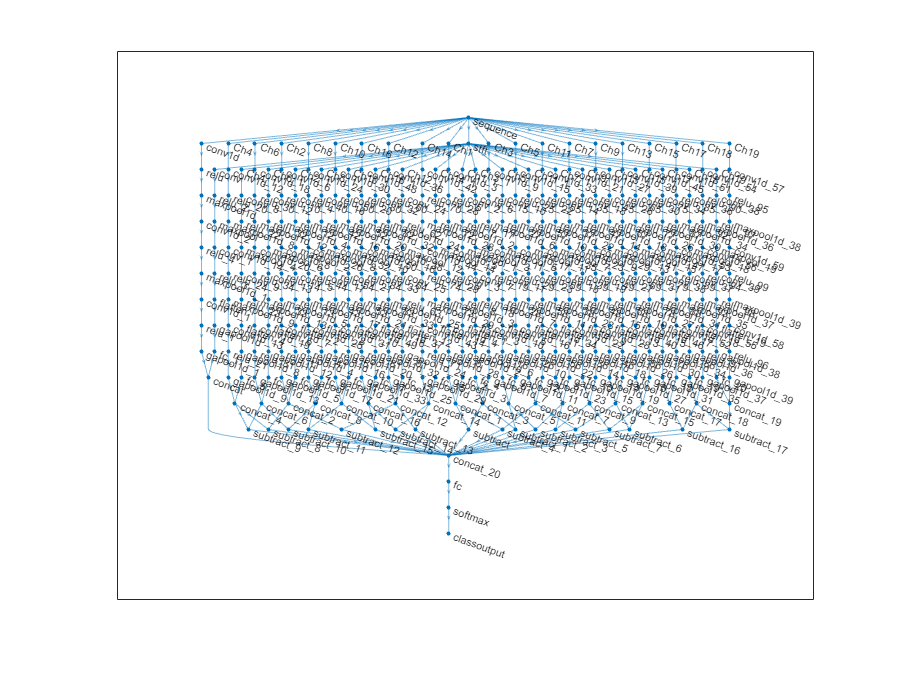

load("SFnet.mat","lgraph_2")
f = figure;
f.Position(4) = f.Position (4) *2;
f.Position(3) = f.Position (3) *2;
plot(lgraph_2)

## Train Network

Only need to do once

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:36 |       29.17% |       33.45% |      15.0494 |     145.0047 |          0.0003 |
|       1 |          50 |       00:08:18 |       37.50% |              |       4.1385 |              |          0.0003 |
|       1 |         100 |       00:16:15 |       45.83% |       45.60% |       2.2992 |       2.0721 |          0.0003 |
|       1 |         150 |       00:19:20 |       33.33% |              |       2.3187 |              |          0.0003 |
|       1 |         200 |       

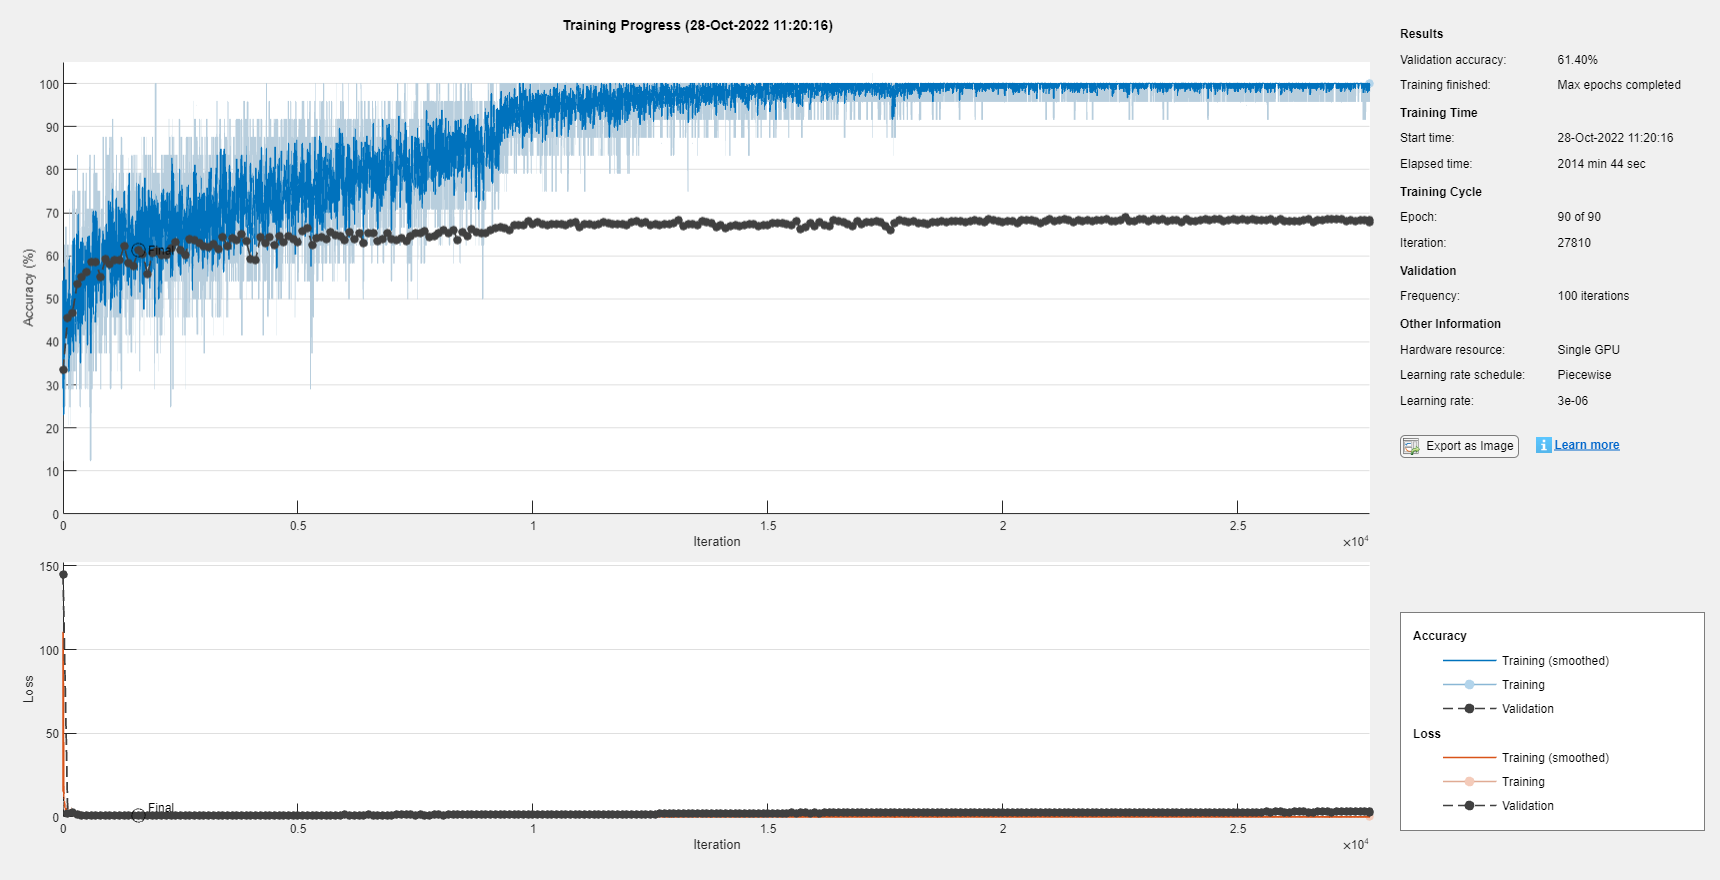

% gpuDevice(1);
% reset(Y_Train);
% reset(X_Test);
% miniBatchSize=24;
% Y_Train.MiniBatchSize=miniBatchSize;
% X_Test.MiniBatchSize=miniBatchSize;
% opts=trainingOptions("adam","Plots","training-progress","ExecutionEnvironment","gpu", ...
% "Shuffle","every-epoch","MiniBatchSize",miniBatchSize,"MaxEpochs",30*3,...
% "InitialLearnRate",3e-4,"LearnRateSchedule","piecewise","LearnRateDropPeriod",30,..."L2Regularization",.001,...
% "OutputNetwork","best-validation-loss","ValidationData",X_Test,"ValidationFrequency",100);
% bnet=trainNetwork(Y_Train,lgraph_2,opts);

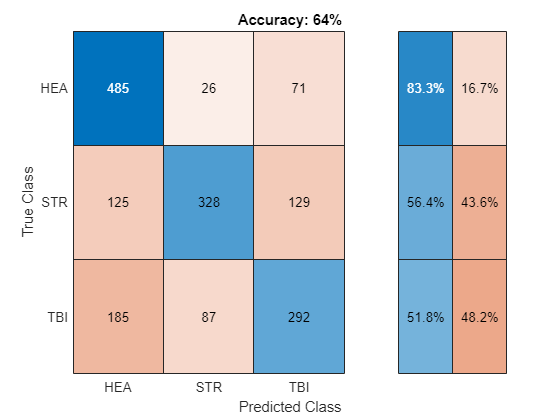

load("SFnet.mat","bnet2");
Snet = MdlResults(bnet2,X_Test,X_Test.Labels);
classify(Snet);

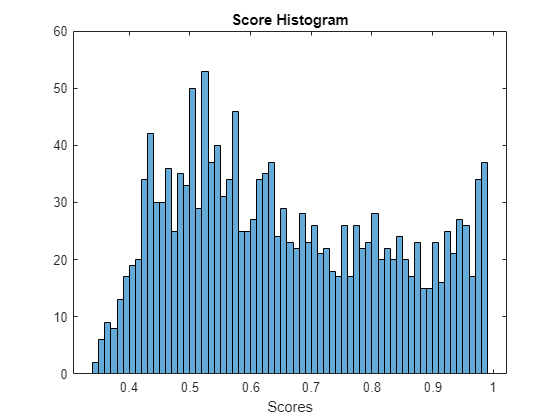

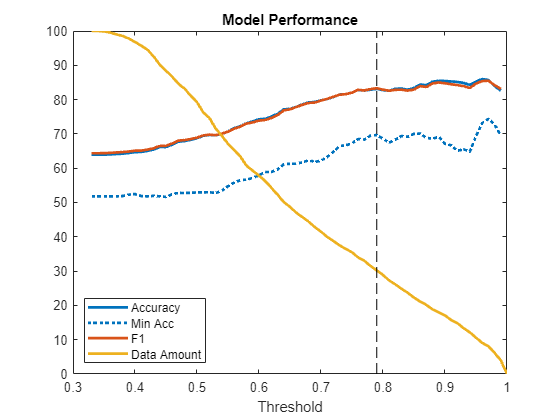

Data Remaining: 0.30208


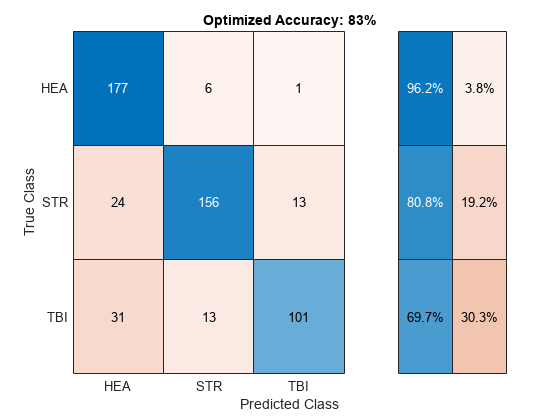

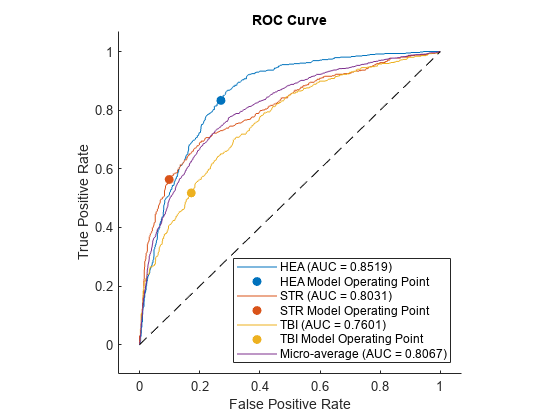

metrics(Snet);

## Supporting Functions

function [CV,IV]=pathname(path,C)
if nargin<2
    C=["HEA","STR","TBI"];
end
d=load("CVIVsplit_LSTM.mat");
j=1;
j2=1;
for k=1:length(C)
    x=d.(C(k)+"_TCV");
    y=d.(C(k)+"_TIV");
    %CV=cell(1,height(x));
    %IV=cell(1,height(y));
    for i=1:height(x)
        if length(C)>1
            CV{j}=fullfile(path,C(k), ...
                [eightdigit(x.Subject(i)),'_',x.Session(i),'_',num2str(x.Date.Year(i)),'_', ...
                doubledigit(x.Date.Month(i)),'_',doubledigit(x.Date.Day(i)), ...
                '-',num2str(x.Min(i)),'.mat']);
        else
            CV{j}=fullfile(path,C(k),eightdigit(x.Subject(i)), ...
                [x.Session(i),'_',num2str(x.Date.Year(i)),'_', ...
                doubledigit(x.Date.Month(i)),'_',doubledigit(x.Date.Day(i)), ...
                '-',num2str(x.Min(i)),'.mat']);
        end
        j=j+1;
    end
    for i=1:height(y)
        if length(C)>1
            IV{j}=fullfile(path,C(k), ...
                [eightdigit(x.Subject(i)),'_',x.Session(i),'_',num2str(x.Date.Year(i)),'_', ...
                doubledigit(x.Date.Month(i)),'_',doubledigit(x.Date.Day(i)), ...
                '-',num2str(x.Min(i)),'.mat']);
        else
            IV{j}=fullfile(path,C(k),eightdigit(x.Subject(i)), ...
                [x.Session(i),'_',num2str(x.Date.Year(i)),'_', ...
                doubledigit(x.Date.Month(i)),'_',doubledigit(x.Date.Day(i)), ...
                '-',num2str(x.Min(i)),'.mat']);
        end
        j2=j2+1;
    end
end
    function y=doubledigit(x)
        y=num2str(x);
        if length(y)<2
            y=['0',y];
        end
    end
    function y=eightdigit(x)
        y=num2str(x);
        if length(y)<8
            y=[repelem('0',8-length(y)),y];
        end
    end
end
function in=MatchSubject(Files,CV)
sFiles=SubSplit(Files);
sCV=unique(SubSplit(CV));
in=ismember(sFiles,sCV);
    function s=SubSplit(x)
        if size(x,1)==1
            x=x';
        end
        s=split(x,'\');
        s=s(:,end);
        s=split(s,'_');
        s=s(:,1);
    end
end

function [y,labels] = TemporalSplit(ds,fs)
reset(ds);
ds.MiniBatchSize = 1;
y = cell(ds.NumObservations*5,1);
for i = 1:ds.NumObservations
    T = read(ds);
    x = cell2mat(T.predictors);
    t = 1 + 5*(i-1);
    labels(t:t+4) = T.responses;
    y{t} = x(:,1:90*fs);
    y{t+1} = x(:,(90*fs+1):end);
    for j = 2:4
        r = randi(90*fs-2)+1;
        y{t+j} = x(:,r:r+(90*fs-1));
    end
end
end

function layers = freezeWeights(layers,excludeLayers)
% layers = freezeWeights(layers) sets the learning rates of all the
% parameters of the layers in the layer array |layers| to zero if they already have weights.
if nargin <2
    excludeLayers = [];
end
layernums = 1:1:size(layers,1);
layernums(excludeLayers) = [];
for ii = layernums
    props = properties(layers(ii));
    for p = 1:numel(props)
        propName = props{p};
        if ~isempty(regexp(propName, 'LearnRateFactor$', 'once'))
            if ~isempty(layers(ii).Weights)
                layers(ii).(propName) = 0;
            end
        end
    end
end

end

function lgraph = createLgraphUsingConnections(layers,connections)

lgraph = layerGraph();
for i = 1:numel(layers)
    lgraph = addLayers(lgraph,layers(i));
end

for c = 1:size(connections,1)
    lgraph = connectLayers(lgraph,connections.Source{c},connections.Destination{c});
end

end